# EDUCAT database visualization

TIP:When requesting new data or starting a new connection  --> right click and select " clear all Output" 

clear
clc
close all
username = "analyst";
userInput = ' password: ';
password = input(userInput,'s');

import classes.measurement
import classes.instrument
import classes.data
m = measurement(username,password);
clc;
clear password userInput username;

 
m.list

ans = 11×6 table
    id              description                  start_time               end_time          count        max    
    ___    _____________________________    ____________________    ____________________    _____    ___________

    106    'test6 [STORE]'                  22-Oct-2019 10:51:09    22-Oct-2019 10:59:56        0    -2147483648
    105    'test_outdoor_22_10_19'          22-Oct-2019 10:42:06    01-Jan-1970 00:00:00    23017          23017
    104    'test_sarah_22_10_19 [STORE]'    22-Oct-2019 09:35:14    22-Oct-2019 09:38:15     9015           9039
    101    'test [STORE]'                   22-Oct-2019 08:39:24    22-Oct-2019 08:39:33        0    -2147483648
     99    'chailey1 [DELETE]'              21-Oct-2019 16:03:57    21-Oct-2019 16:05:39     5106   

## Declaration of measurement

id=  ;
if( size(find(m.list.id == id),1)==1 && m.list.count(find(m.list.id == id,1)) > 2)
    disp('ID exists, running...')
    m=m.set_measurement_ID(id);
    m = m.declaration();
    % ******* get data ********
    m = m.get_dataset_DB();
    disp("done")
    duration = datetime(m.end_time, 'convertfrom','posixtime') - datetime(m.start_time, 'convertfrom','posixtime');
    disp(['duration: ' datestr(duration,'HH:MM:SS.FFF')])
elseif m.list.count(find(m.list.id == id,1)) < 2
    disp("measurement contains no data")
else
    disp("ID does not exist in database")
end

ID exists, running...


done


duration: 00:01:42.140


## Export data to workspace

m.exportData();

 

## Plot all measurement information

close all;
 
display(['Moment of measurement: ' datestr(datetime(m.start_time, 'convertfrom','posixtime'),'yyyy-mm-dd HH:MM:SS.FFF')]);

Moment of measurement: 2019-10-21 16:03:57.740


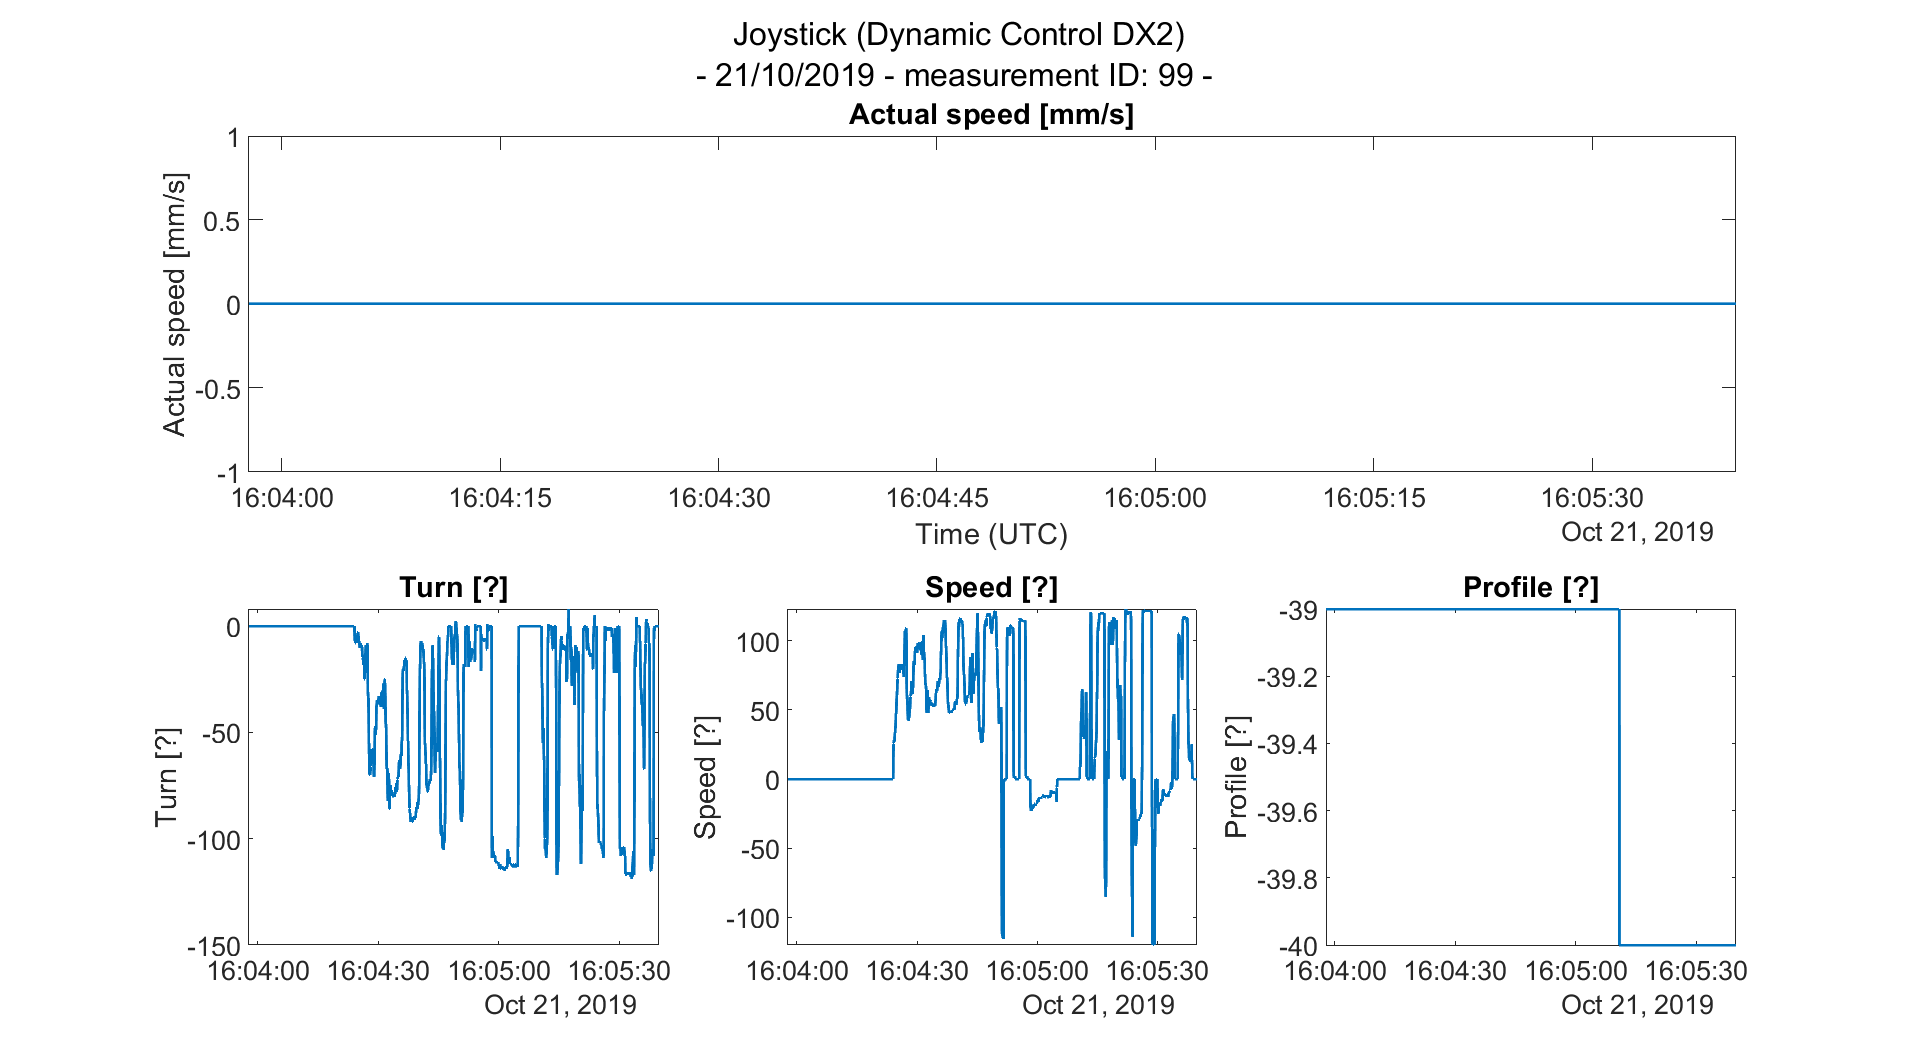

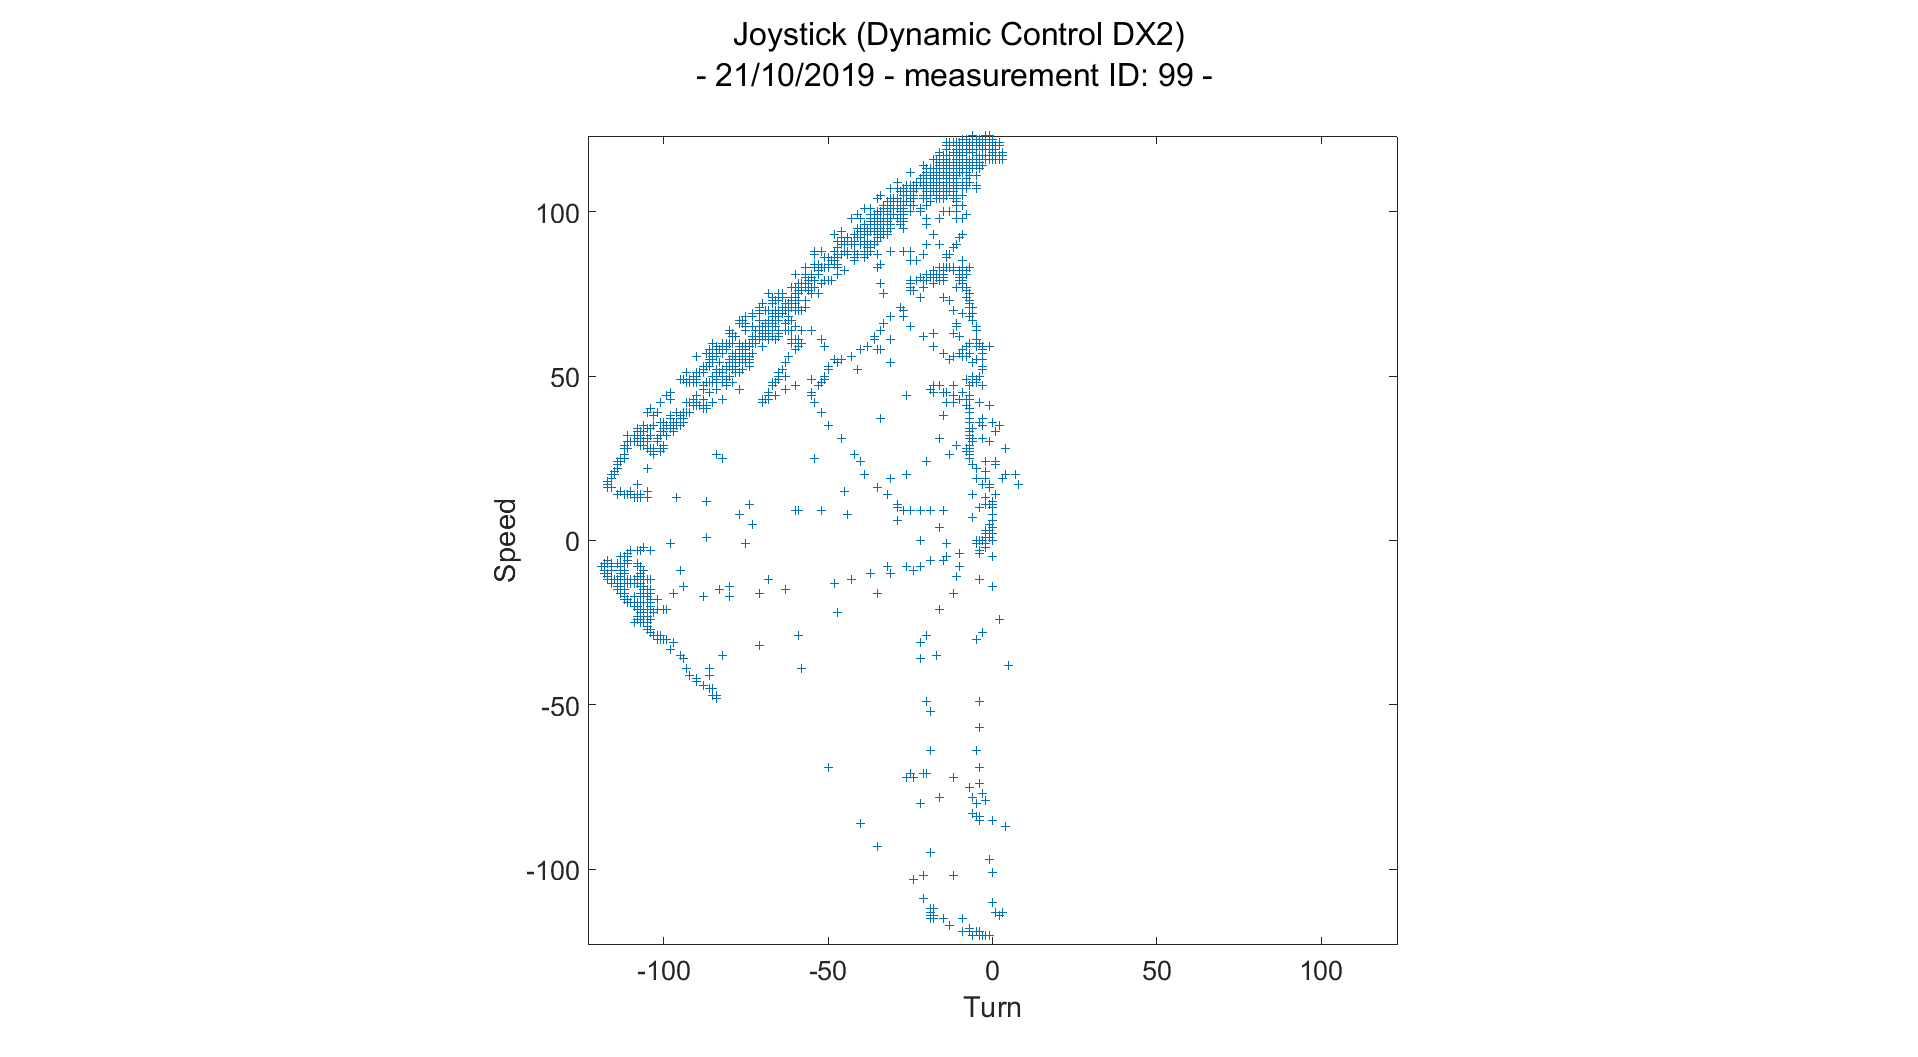

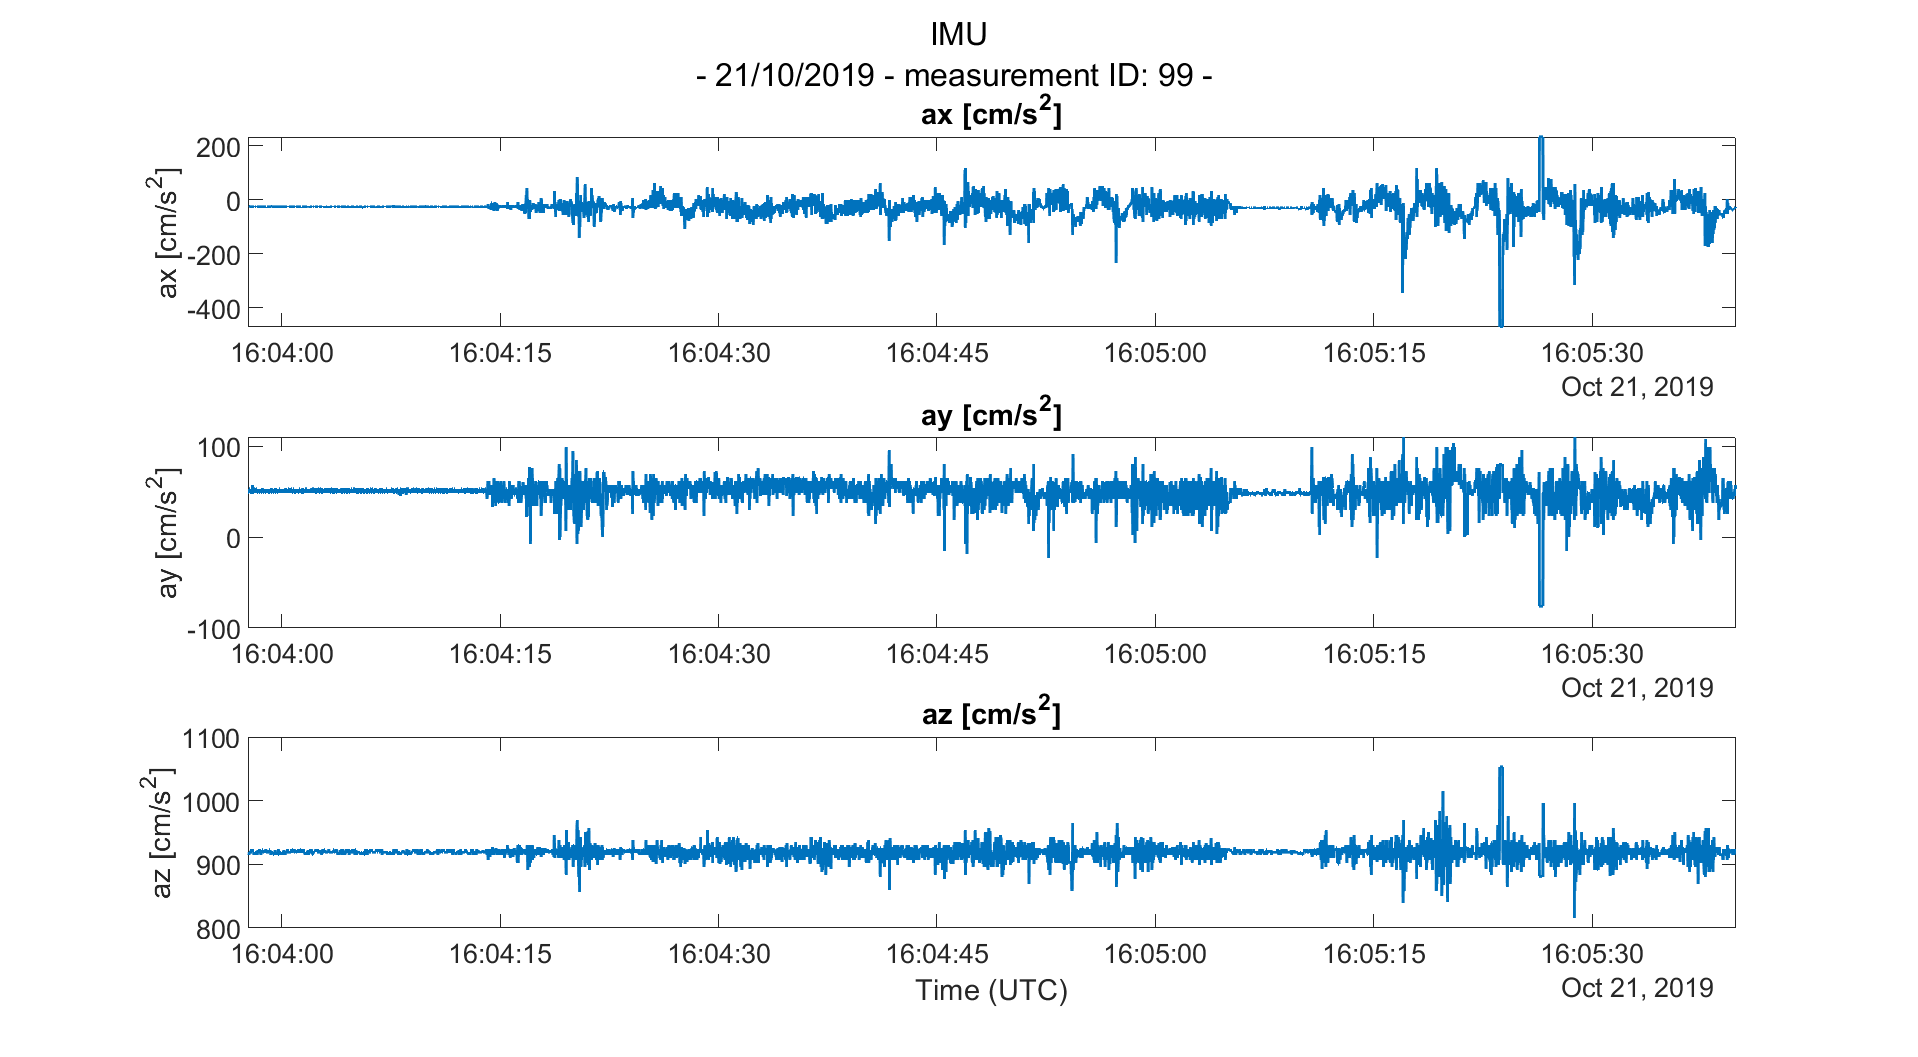

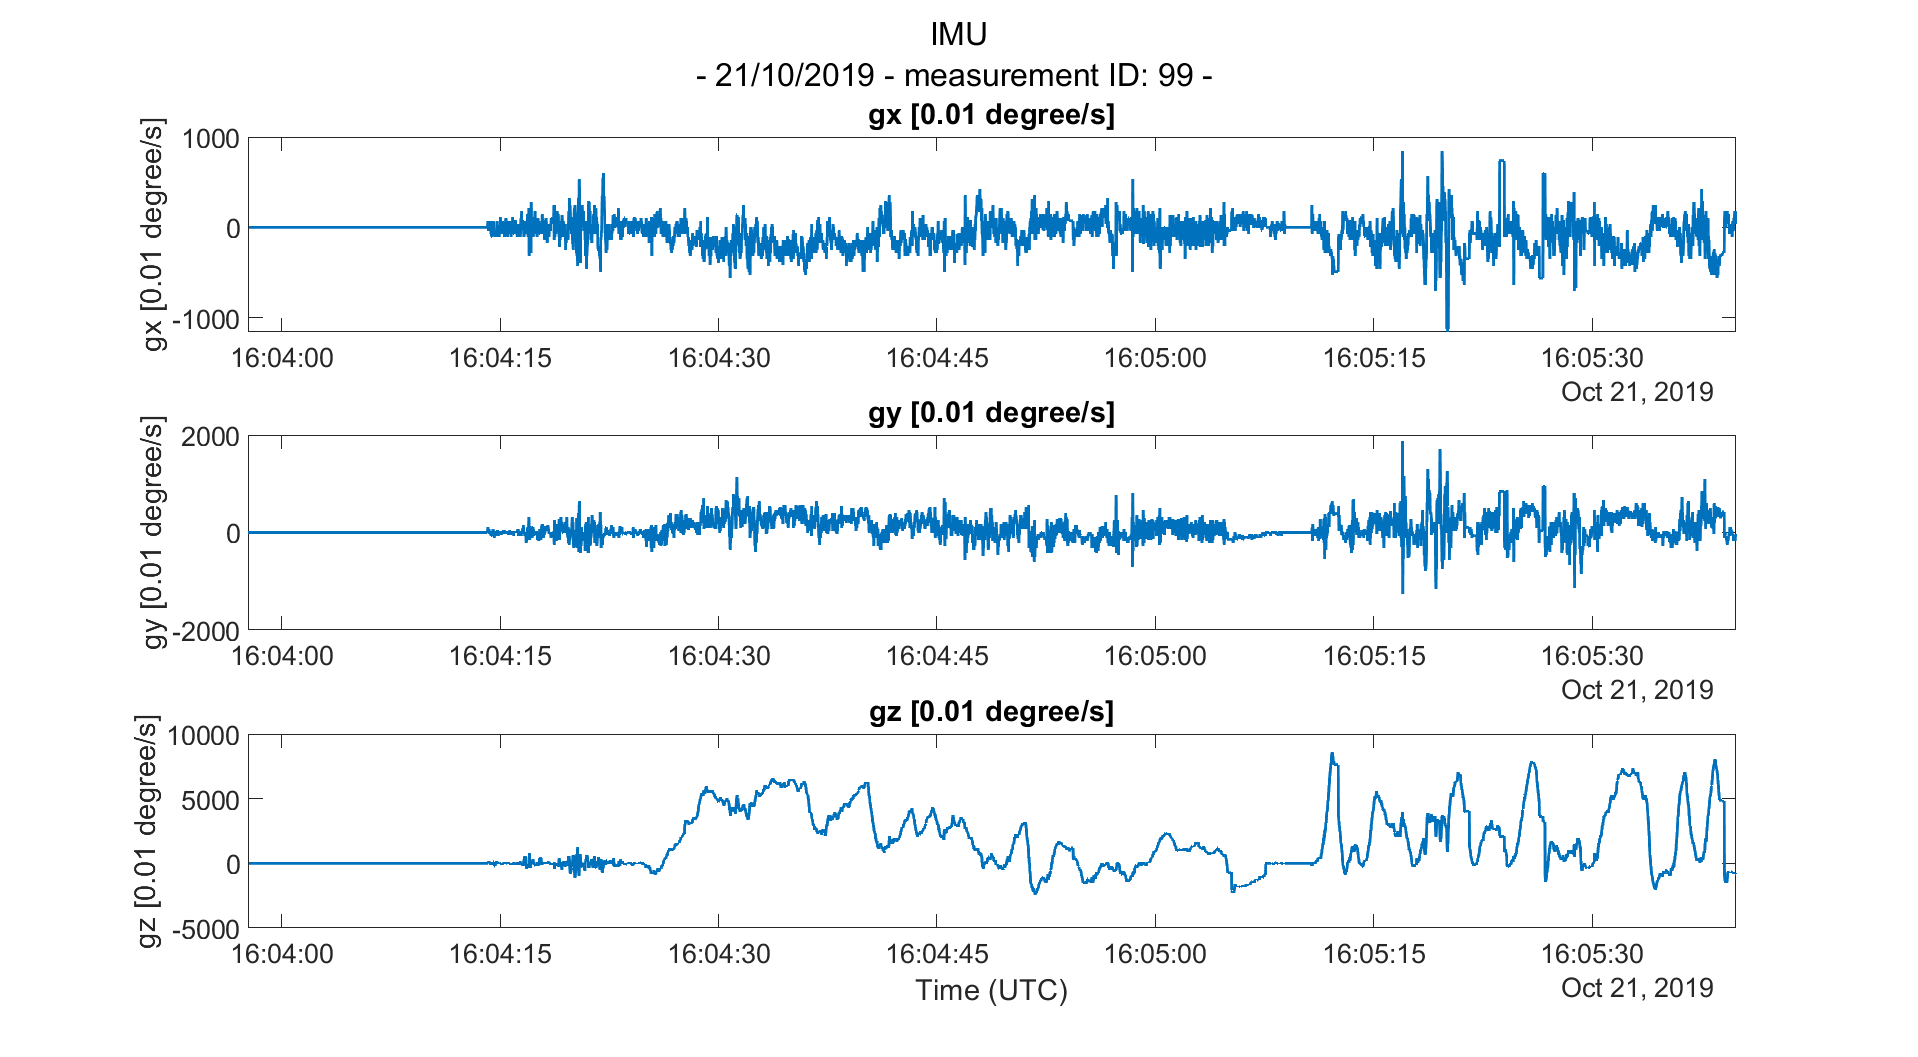

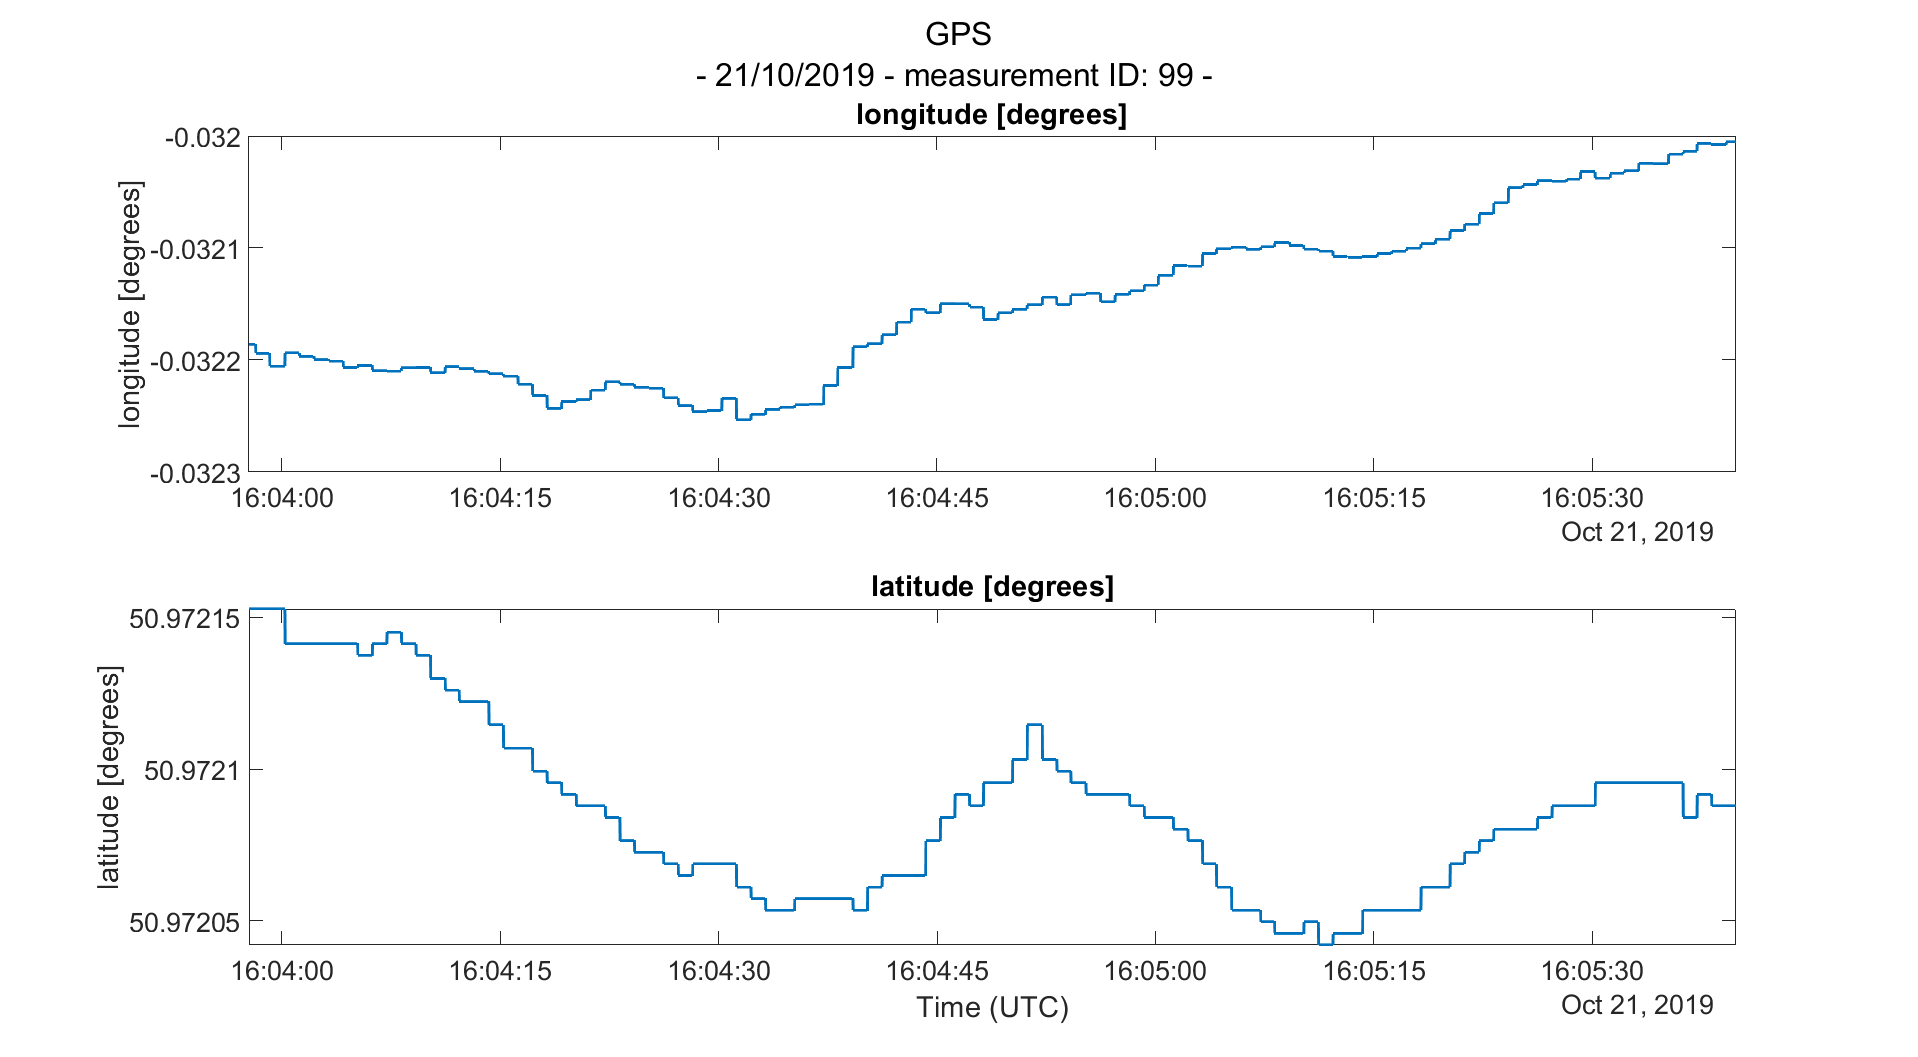

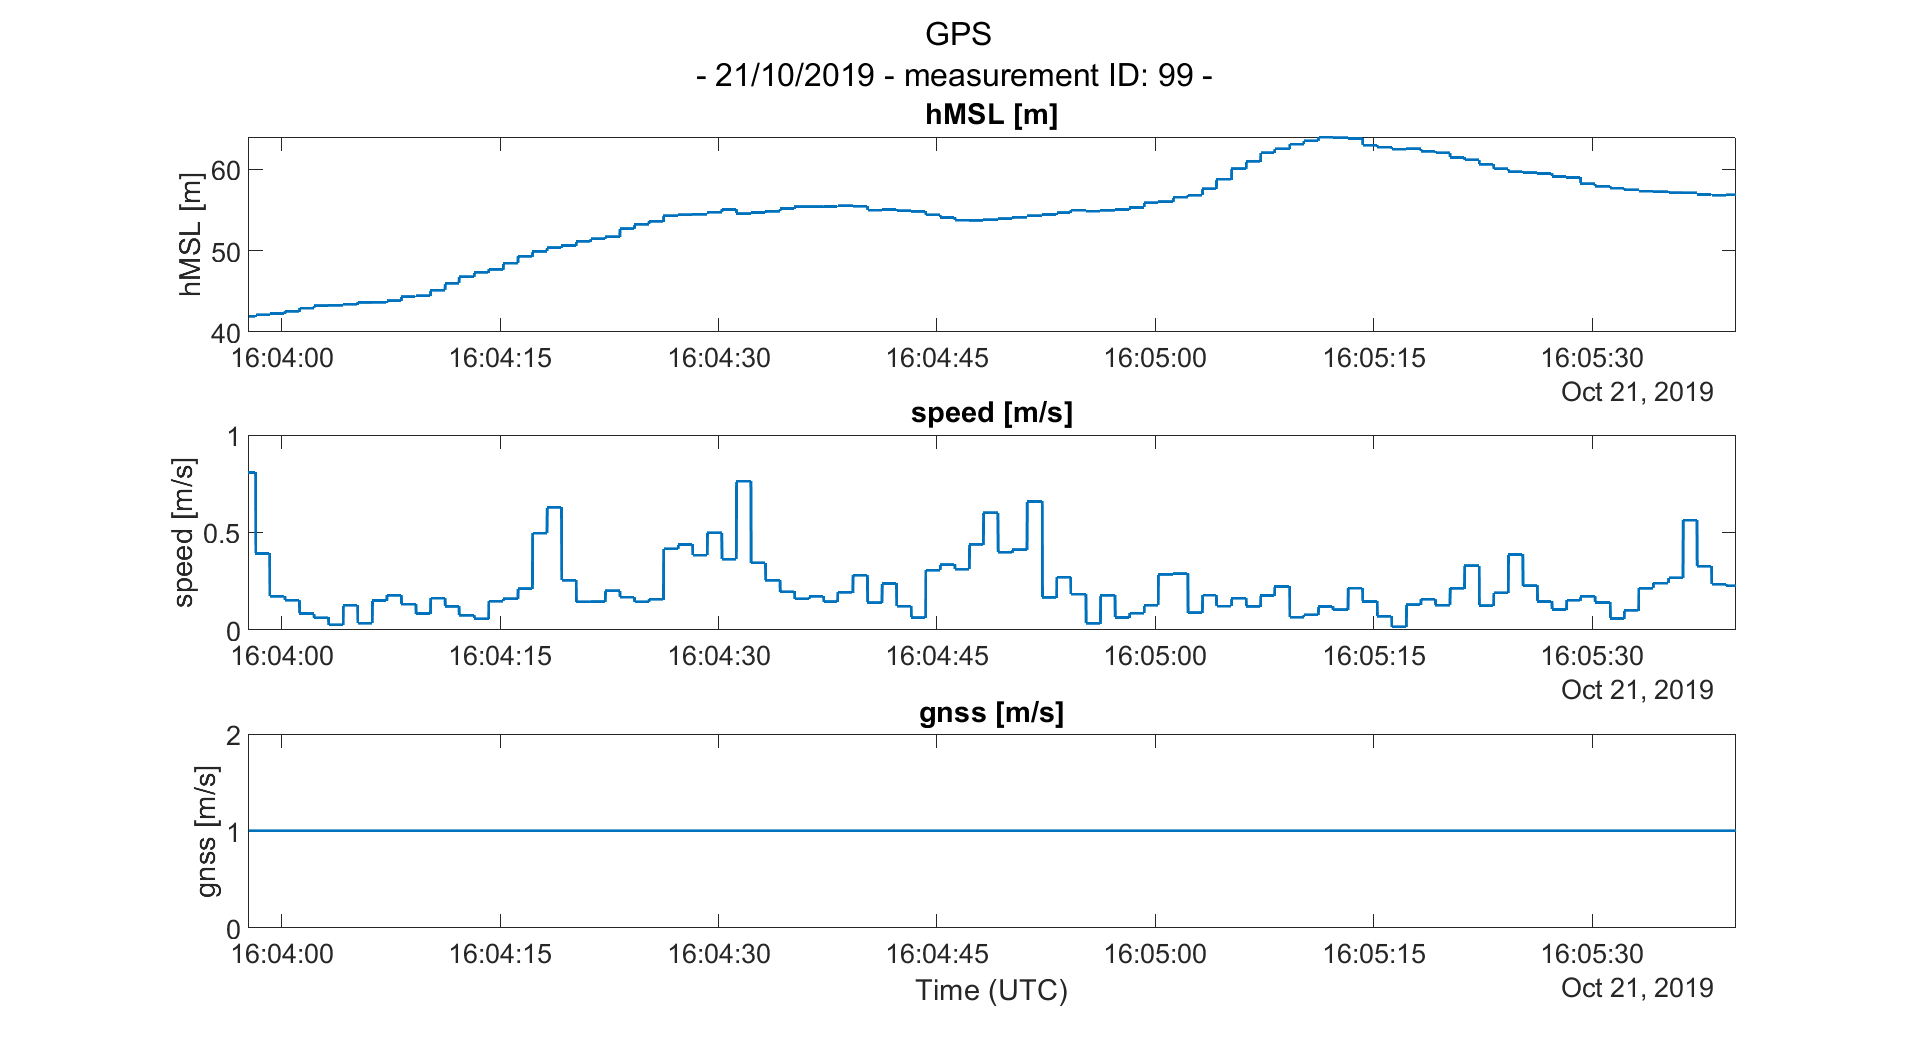

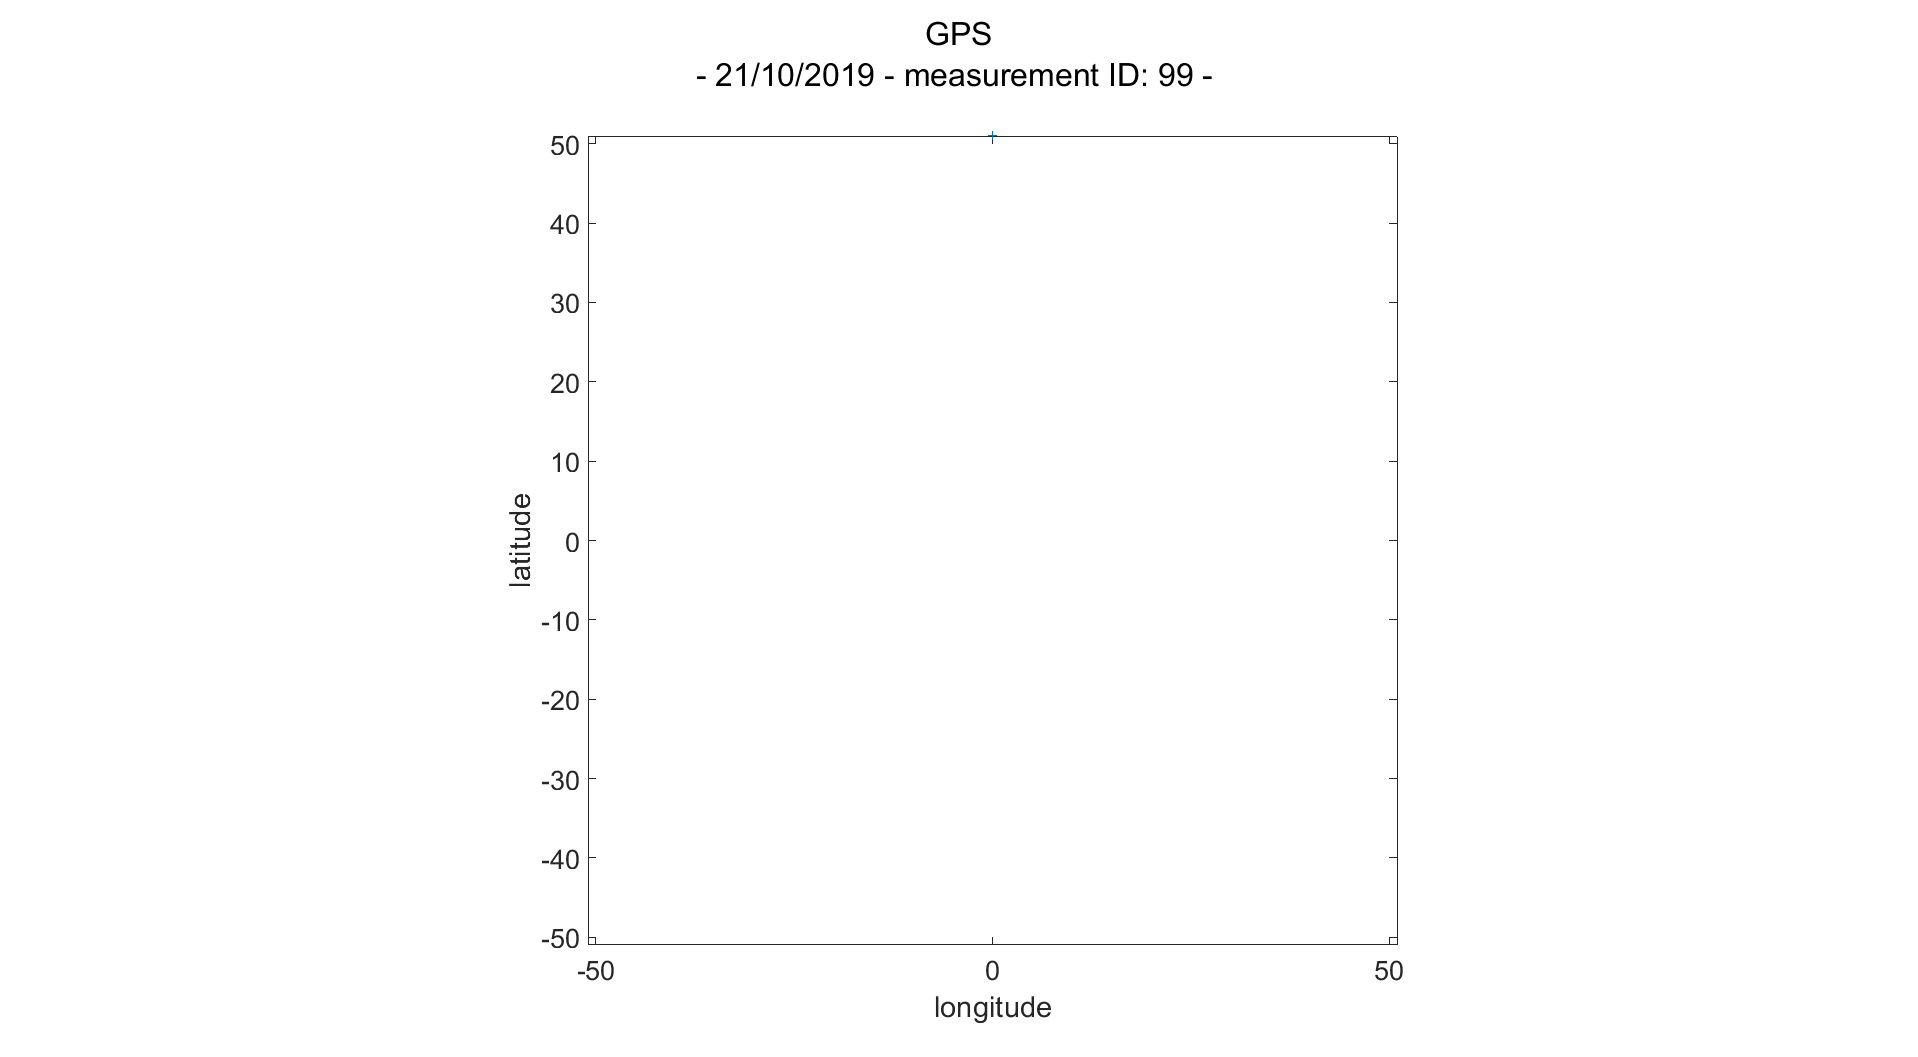

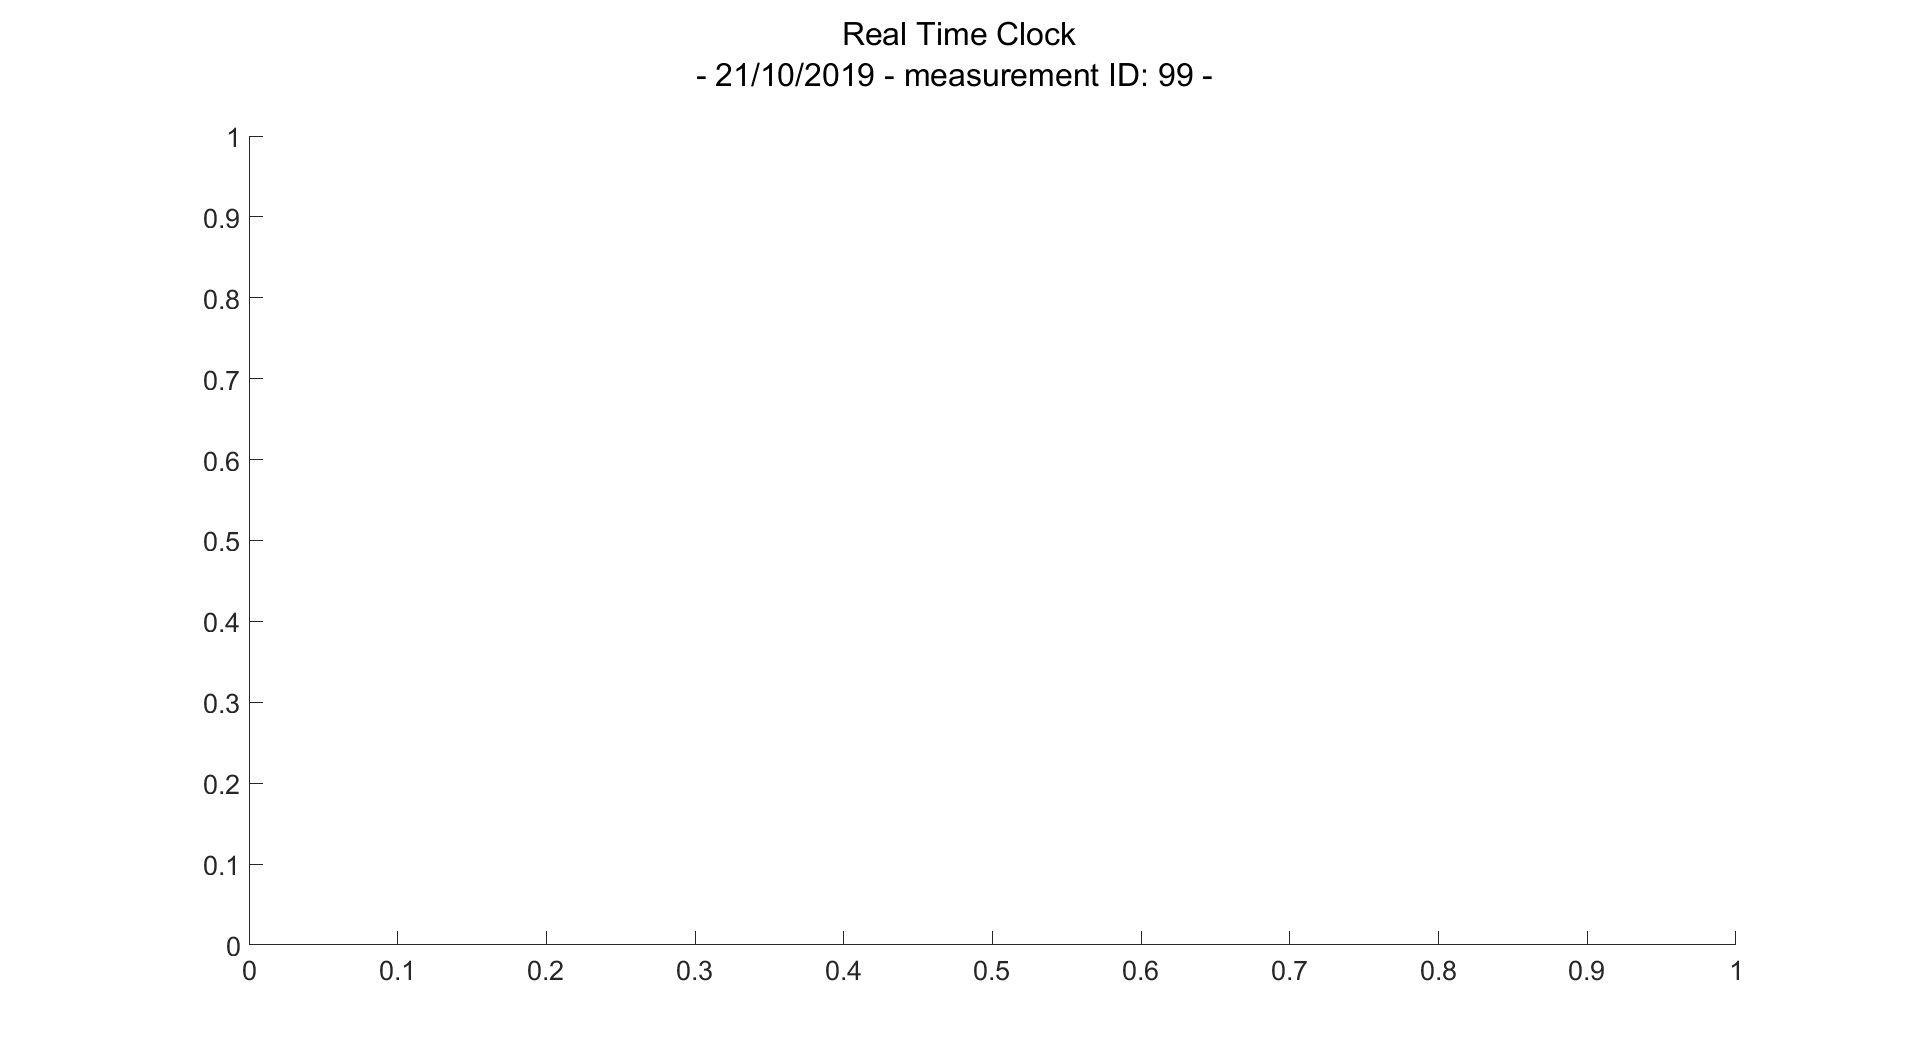

    "Real Time Clock"    " is not yet programmed"



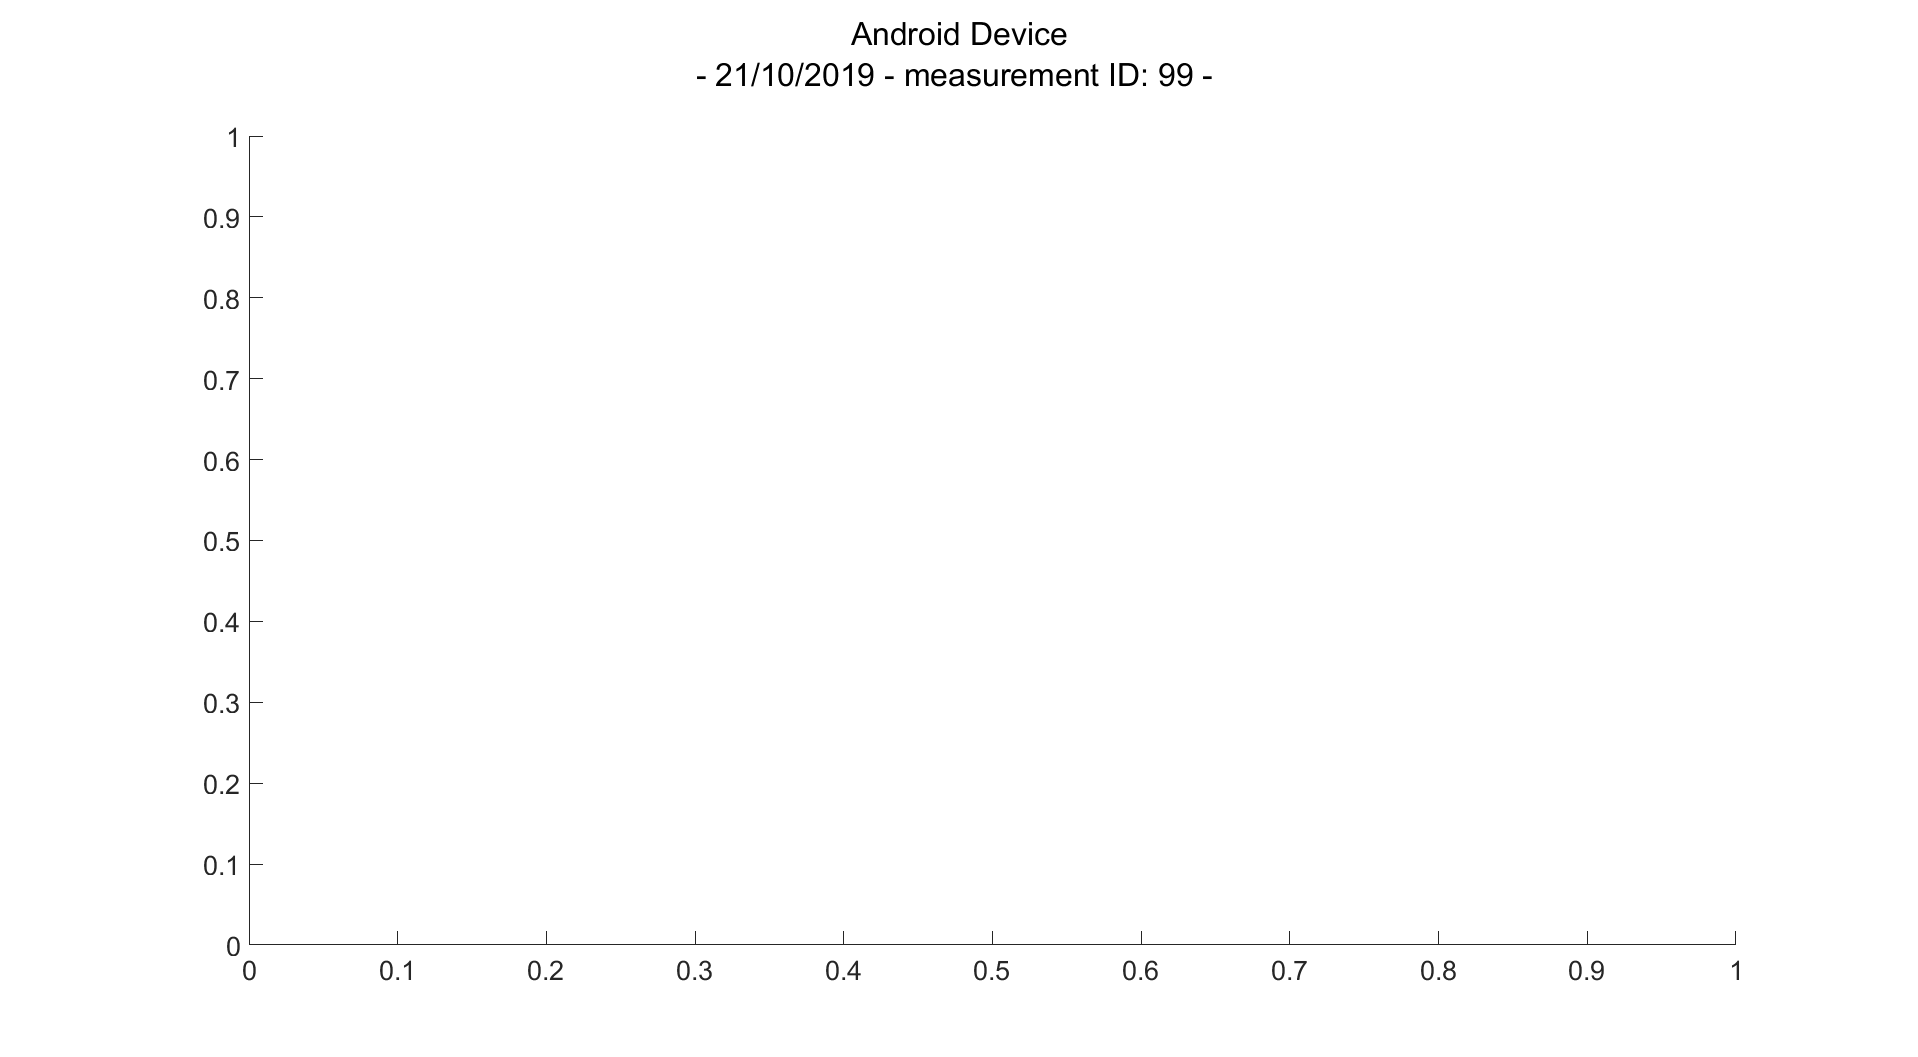

    "Android Device"    " is not yet programmed"



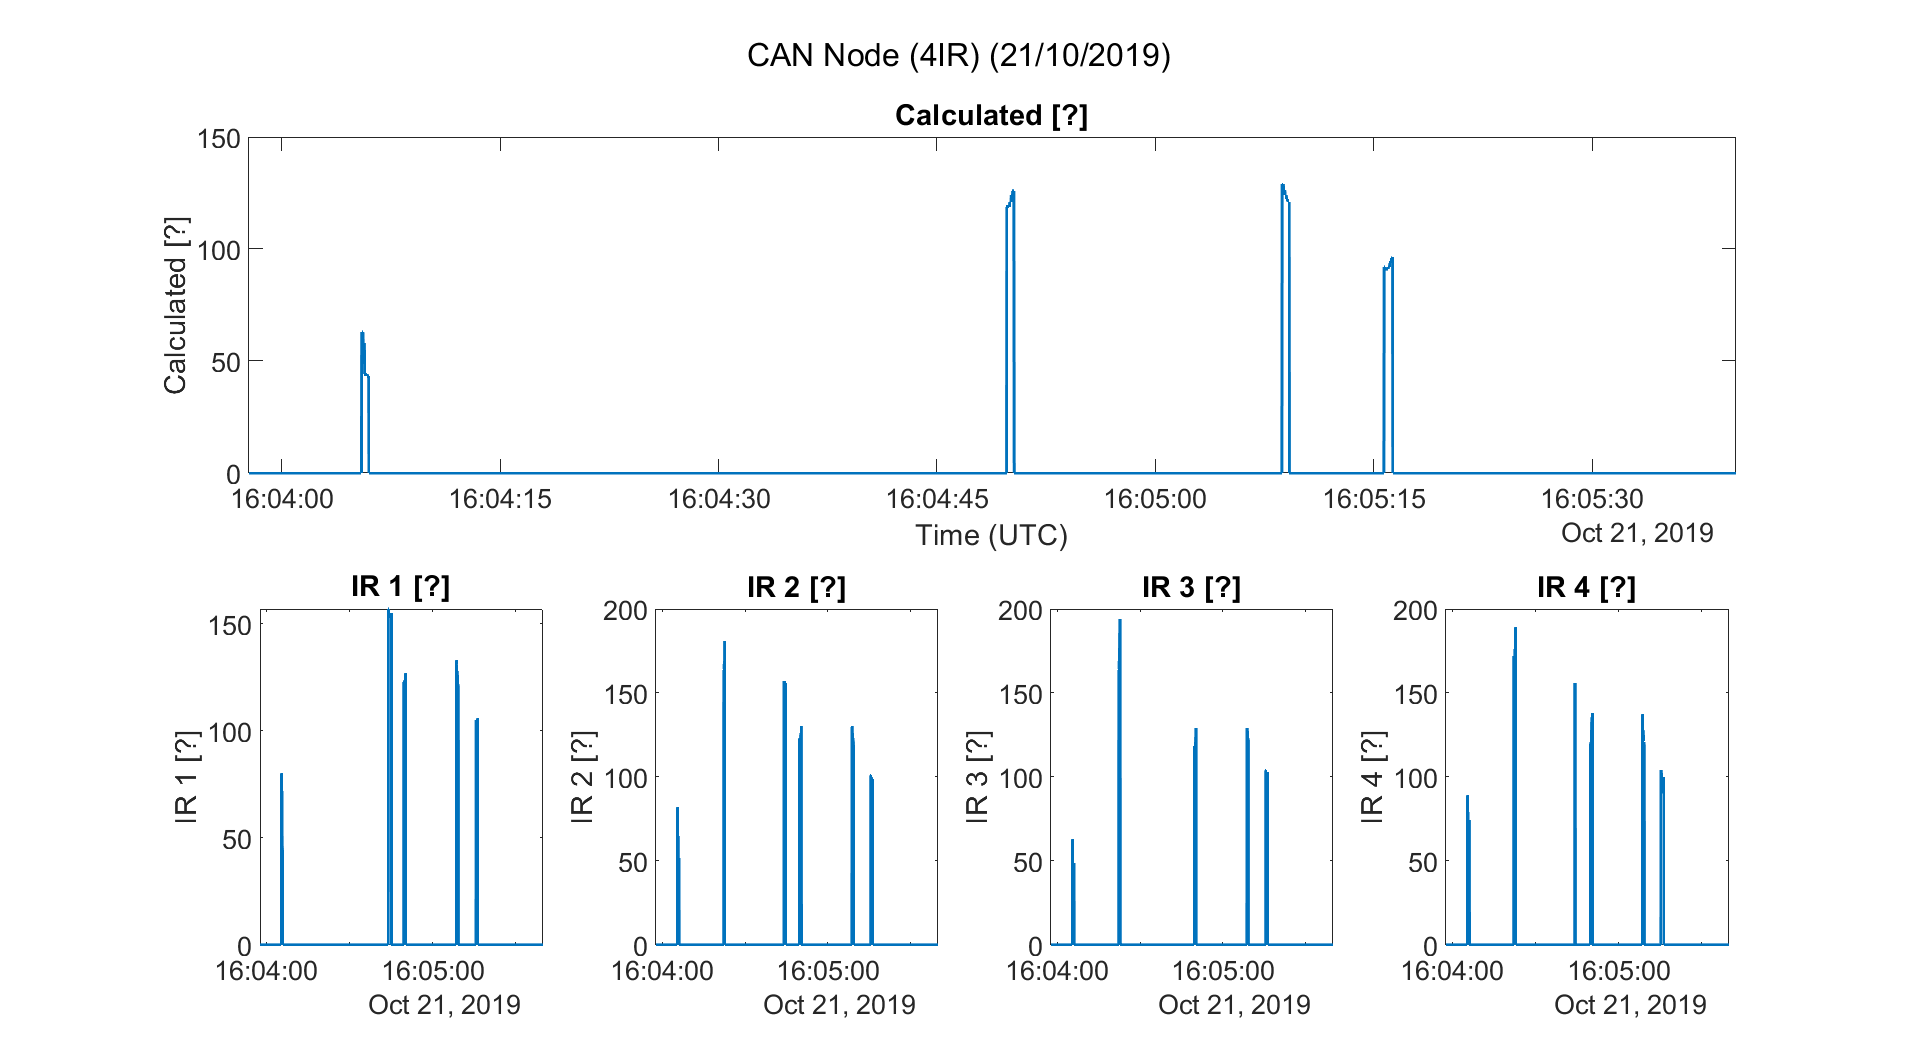

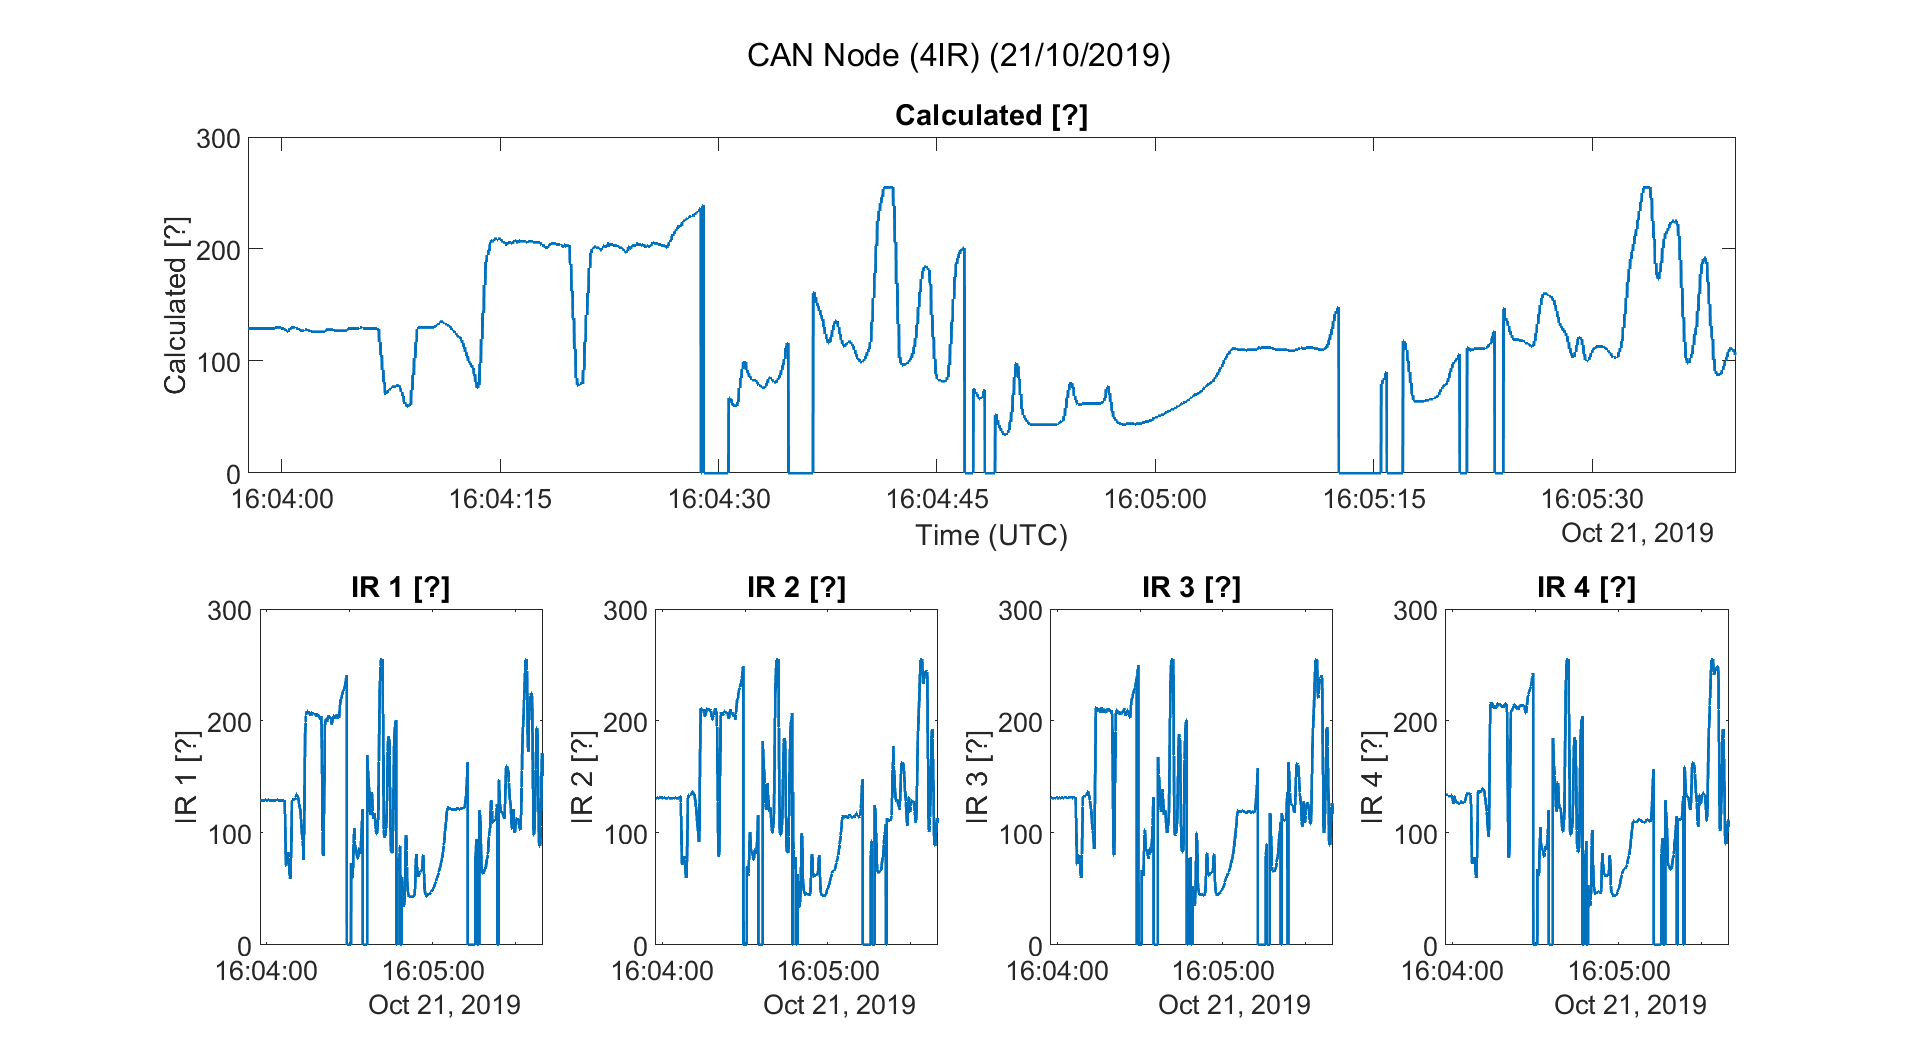


if  exist('id','var')
    if  m.list.count(find(m.list.id == id,1)) > 2
        m.plot_all();
    elseif m.list.count < 2
        disp("measurement contains no data")
    else
        disp("ID does not exist in database")
    end
else
    disp("get first the data")
end

## save workspace to .mat file in data folder

StoreName = "20191021";

 

filename = strcat(StoreName,'.mat');
if ~exist("data", 'dir')
    mkdir("data")
end
store = fullfile(pwd, "data",filename);
save(store);


## Own analysis: type your own commands

 
time = (1:size(m.instruments(1,2).data(1,6).values,2))*0.02 + m.start_time;
figure();
fontsize = 20;
set(gca,'fontsize',fontsize) % set fontsize of the plot to 20
set(gcf, 'Position', get(0,'Screensize')); % automatic full screen
set(0, 'DefaultAxesFontSize', fontsize);
plot(time,m.instruments(1,1).data(1,2).values,'LineWidth',2)
ylabel("Turn",'fontsize',fontsize);
ax1 = gca;
yyaxis right
plot(time, m.instruments(1,2).data(1,6).values,'LineWidth',2)
xlabel('Time [s]','fontsize',fontsize);
ylabel("gz",'fontsize',fontsize);
xlim(([min(time) (max(time))]));
title("gz vs turn" ,'fontsize',fontsize);
legend(["turn","gz"]);


### Heatmaps

figure()
heatmap([m.instruments(1,1).data(1,2).values m.instruments(1,2).data(1,6).values])






